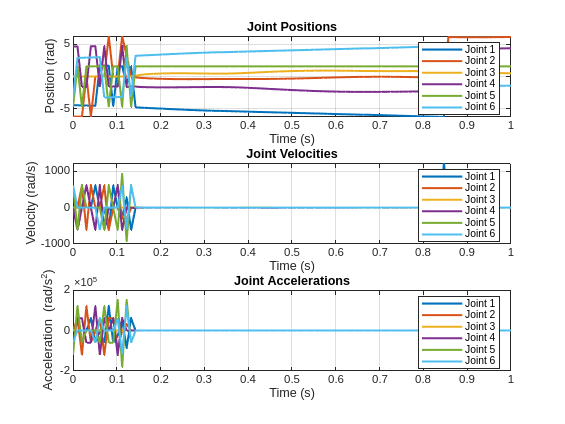

close all;
clc;

% Load UR5e robot
robot = loadrobot("universalUR5e");
robot.DataFormat = 'row';

% Add gripper (optional)
ur5e = exampleHelperAddGripper(robot);

% Home position
homePosition = deg2rad([-15, -126, 113, -80, -91, 76]);
for i = 1:6
    ur5e.Bodies{i+2}.Joint.HomePosition = homePosition(i);
end

% Inverse kinematics solver
ik = inverseKinematics('RigidBodyTree', ur5e);
weights = [1, 1, 1, 1, 1, 1];
initialGuess = homePosition;

% Define waypoints with 4 control points
waypoints = [-0.6, -0.4, 0.4, 0.7, 0.9, 0.8;  % X positions
             0.3, 0.9, 0.8, 0.4, 0.0, 0.3;  % Y positions
             0.0, 0.2, 0.4, 0.0, 0.2, 0.0]; % Z positions

% Transpose waypoints to match Catmull-Rom requirements
controlPoints = waypoints';

% Apply Catmull-Rom spline
numSamples = 100; % Total interpolated points
interpolatedPoints = [];
for i = 2:size(controlPoints, 1)-2
    P_prev = controlPoints(i-1, :);
    P_curr = controlPoints(i, :);
    P_next = controlPoints(i+1, :);
    P_next2 = controlPoints(i+2, :);
    
    for t = linspace(0, 1, numSamples / (size(controlPoints, 1)-3))
        C_x = 0.5 * ((-t^3 + 2*t^2 - t) * P_prev(1) + ...
                     (3*t^3 - 5*t^2 + 2) * P_curr(1) + ...
                     (-3*t^3 + 4*t^2 + t) * P_next(1) + ...
                     (t^3 - t^2) * P_next2(1));
                 
        C_y = 0.5 * ((-t^3 + 2*t^2 - t) * P_prev(2) + ...
                     (3*t^3 - 5*t^2 + 2) * P_curr(2) + ...
                     (-3*t^3 + 4*t^2 + t) * P_next(2) + ...
                     (t^3 - t^2) * P_next2(2));
                 
        C_z = 0.5 * ((-t^3 + 2*t^2 - t) * P_prev(3) + ...
                     (3*t^3 - 5*t^2 + 2) * P_curr(3) + ...
                     (-3*t^3 + 4*t^2 + t) * P_next(3) + ...
                     (t^3 - t^2) * P_next2(3));
                 
        interpolatedPoints = [interpolatedPoints; C_x, C_y, C_z];
    end
end

% Compute IK for interpolated points
interpolatedConfigs = [];
for i = 1:size(interpolatedPoints, 1)
    T = trvec2tform(interpolatedPoints(i, :));  % Convert to homogeneous transformation
    [theta, ~] = ik('tool0', T, weights, initialGuess);
    interpolatedConfigs = [interpolatedConfigs; theta];
    initialGuess = theta;  % Update initial guess
end

% Time vector (evenly spaced for interpolated points)
time = linspace(0, 1, size(interpolatedPoints, 1));

% Compute joint positions, velocities, and accelerations
jointPositions = interpolatedConfigs; % Positions are the configurations
jointVelocities = diff(jointPositions) ./ diff(time'); % Approximate velocities
jointAccelerations = diff(jointVelocities) ./ diff(time(1:end-1)'); % Approximate accelerations

% Add zeros for alignment with time vector (since diff reduces length)
jointVelocities = [jointVelocities; zeros(1, size(jointVelocities, 2))];
jointAccelerations = [jointAccelerations; zeros(2, size(jointAccelerations, 2))];

% Plot positions, velocities, and accelerations for each joint
figure;
for joint = 1:size(jointPositions, 2)
    % Joint positions
    subplot(3, 1, 1);
    plot(time, jointPositions(:, joint), 'LineWidth', 1.5);
    hold on;
    title('Joint Positions');
    xlabel('Time (s)');
    ylabel('Position (rad)');
    grid on;

    % Joint velocities
    subplot(3, 1, 2);
    plot(time, jointVelocities(:, joint), 'LineWidth', 1.5);
    hold on;
    title('Joint Velocities');
    xlabel('Time (s)');
    ylabel('Velocity (rad/s)');
    grid on;

    % Joint accelerations
    subplot(3, 1, 3);
    plot(time, jointAccelerations(:, joint), 'LineWidth', 1.5);
    hold on;
    title('Joint Accelerations');
    xlabel('Time (s)');
    ylabel('Acceleration (rad/s^2)');
    grid on;
end

% Add legends after all plots are drawn
subplot(3, 1, 1);
legend("Joint 1", "Joint 2", "Joint 3", "Joint 4", "Joint 5", "Joint 6");
subplot(3, 1, 2);
legend("Joint 1", "Joint 2", "Joint 3", "Joint 4", "Joint 5", "Joint 6");
subplot(3, 1, 3);
legend("Joint 1", "Joint 2", "Joint 3", "Joint 4", "Joint 5", "Joint 6");

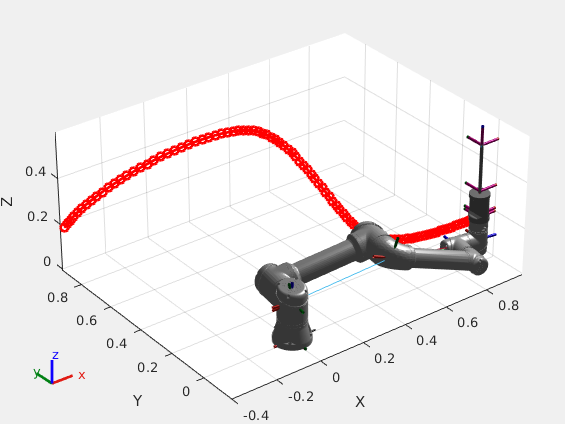



% Visualize the robot's path
figure;
show(ur5e, homePosition, 'Frames', 'on', 'PreservePlot', true);
hold on;

% Plot interpolated trajectory
plot3(interpolatedPoints(:, 1), interpolatedPoints(:, 2), interpolatedPoints(:, 3), 'ro-', 'LineWidth', 2);

% Animate the robot motion
for i = 1:size(interpolatedConfigs, 1)
    show(ur5e, interpolatedConfigs(i, :), 'Frames', 'on', 'PreservePlot', false);
    pause(0.05); % Adjust for smooth animation
end

grid on;
axis equal;
view(3);